# Comparizon of test signals

## load sample impulre response

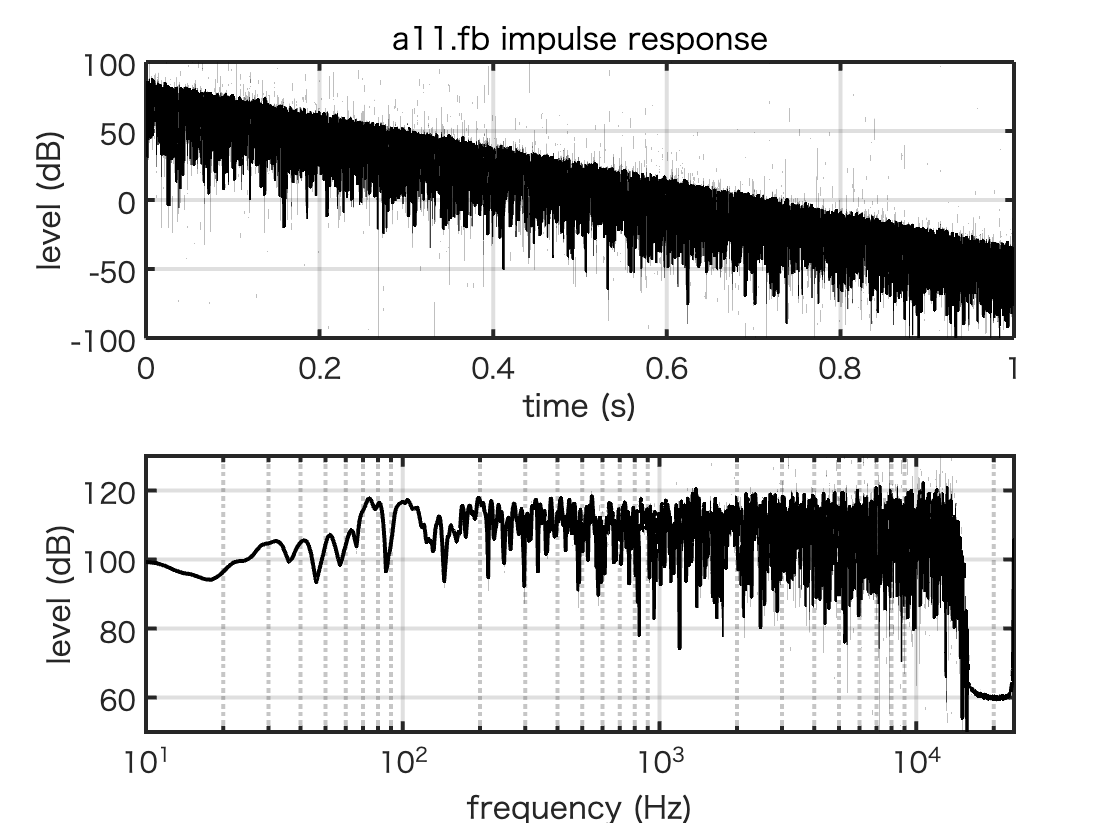

fid = fopen("a11.fb","r",'ieee-le');
a11 = fread(fid,'float32');
fs = 48000;
la11 = length(a11);
fx = (0:la11-1)'/la11*fs;
figure;
tiledlayout(2,1);
t1 = nexttile;
tt = (1:la11)'/fs;
plot(tt,20*log10(abs(a11)),"k","LineWidth",2);grid on;
axis([0 1 -100 100])
set(gca,"LineWidth",2,"fontsize",14)
title("a11.fb impulse response")
xlabel('time (s)')
ylabel('level (dB)')
t2 = nexttile;
semilogx(fx,20*log10(abs(fft(a11))),"k","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",14)
%title("Finite length Gaussian noise")
xlabel('frequency (Hz)')
ylabel('level (dB)')
axis([10 fs/2 50 130])
print -dpng a11Impulse.png

## Log-sweep tone test

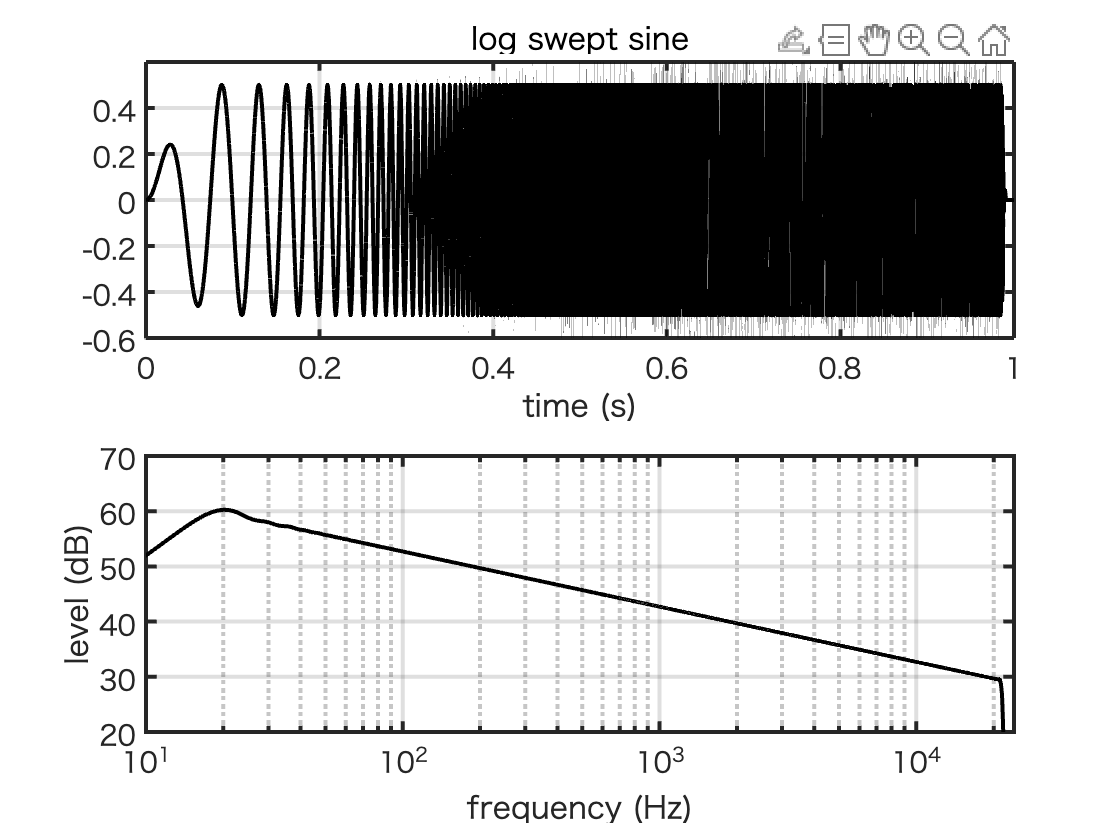

exita = sweeptone(0.99,0.01,fs);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = 1:round(0.1*fs):round(3.9*fs);
stdErr = zeros(length(headLoc),1);
for ii = 1:length(headLoc)
    seleIdx = headLoc(ii)+(1:la11);
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx);
    hEst = real(ifft(fft(ySeg)./fft(xTstSeg)));
    stdErr(ii) = 20*log10(std(hEst-a11)/std(a11));
end
figure;
tiledlayout(2,1)
t1 = nexttile;
plot((1:fs)/fs,exita,"k","LineWidth",2);grid on
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
axis([0 1 -0.6 0.6])
title("log swept sine")
t2 = nexttile;
semilogx(fx,20*log10(abs(fft(exita))),"k","LineWidth",2);grid on
set(gca,"LineWidth",2,"fontsize",14)
%set(gca,"xlim",[10 fs/2])
axis([10 fs/2 20 70])
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng logSStestSignal.png

## check error

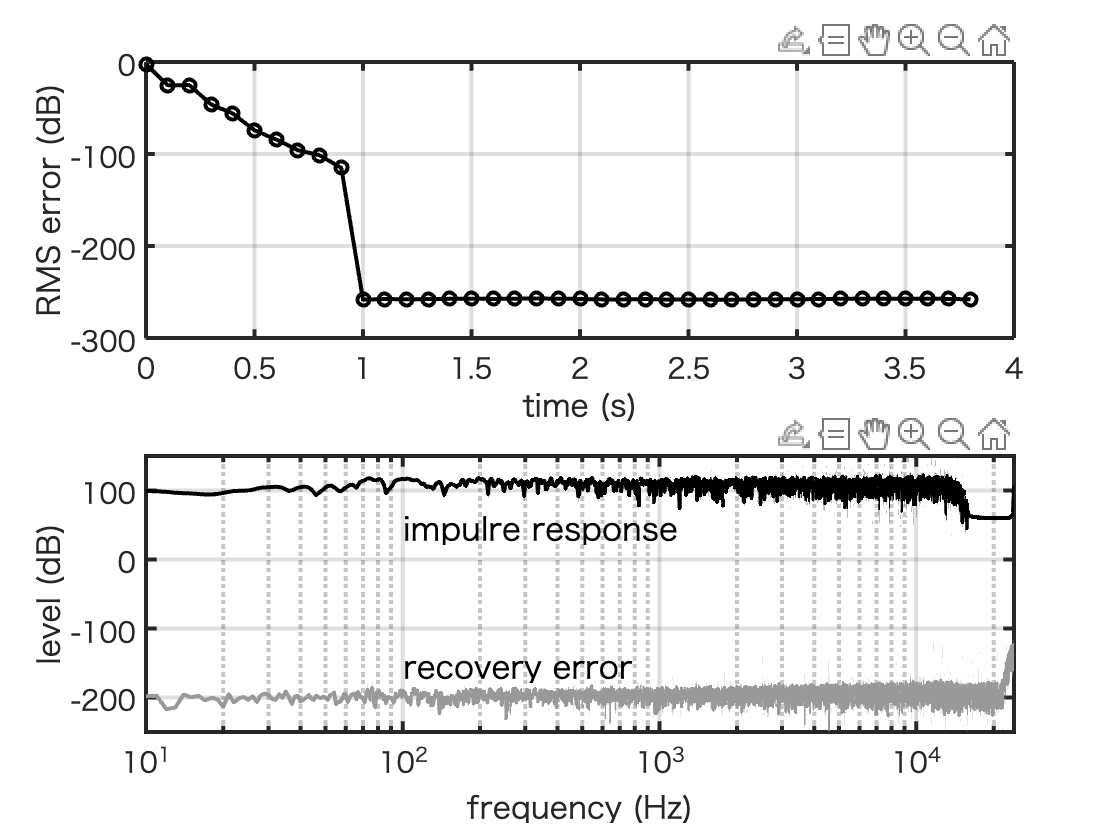

figure;
tiledlayout(2,1);
t1 = nexttile;
plot(headLoc/fs,stdErr,"ko-","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
ylabel('RMS error (dB)')
t2 = nexttile;
semilogx(fx,20*log10(abs(fft(a11))),"k","LineWidth",2);grid on;
hold all
semilogx(fx,20*log10(abs(fft(a11-hEst))),"LineWidth",2,"Color",[0.6 0.6 0.6]);
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
text(100,50,"impulre response","FontSize",16)
text(100,-150,"recovery error","FontSize",16)
axis([10 fs/2 -250 150])
%set(gcf,"position",[680 458 560 240])
print -dpng recoveryError.png

## Log-sweep tone SNR test

exita = sweeptone(0.99,0.01,fs);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(la11,length(snrList));
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:la11);
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx)+std(y(seleIdx))*randn(la11,1)*10^(-snrList(ii)/20);
    hEst = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEst-a11)));
    stdErr(ii) = 20*log10(std(hEst-a11)/std(a11));
end
figure;
set(gcf,"position",[680 458 560 240])
%tiledlayout(2,1)
%t1 = nexttile;
semilogx(fx,20*log10(abs(fft(a11))),"k","LineWidth",2);grid on
axis([10 fs/2 0 130])
hold all
colorLevel = 0.75;
hops = 83;
for ii = 1:length(snrList)
semilogx(fx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(800,hops,num2str(snrList(ii)),"fontsize",14)
hops = hops-20;
end
title("Gaussian noise")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
%print -dpng logSSmesGaussianErr.png

## MLS

exita = mls(2^16-1);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = 1:round(0.1*fs):round(3.9*fs);
stdErr = zeros(length(headLoc),1);
for ii = 1:length(headLoc)
    seleIdx = headLoc(ii)+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx);
    hEst = real(ifft(fft(ySeg)./fft(xTstSeg)));
    hEstTrim = hEst(1:la11);
    stdErr(ii) = 20*log10(std(hEstTrim-a11)/std(a11));
end

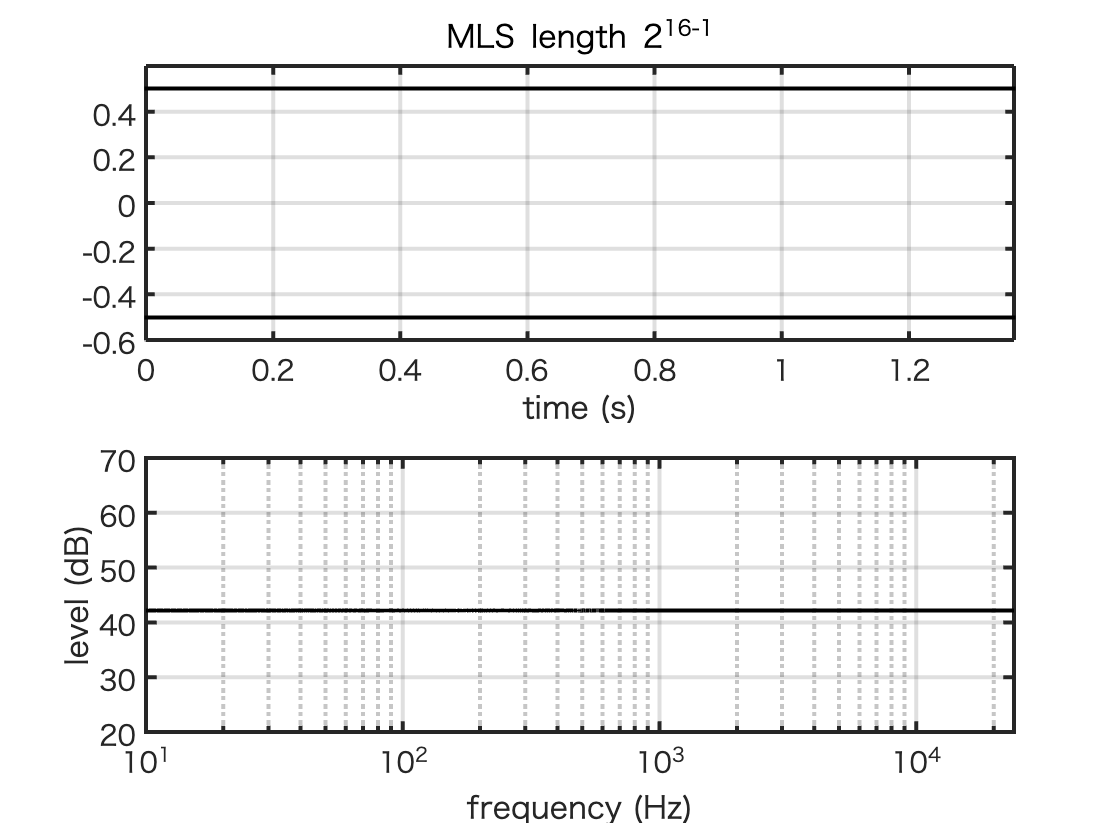


figure;
tiledlayout(2,1)
nexttile
plot((1:lPeriod)/fs,exita,"k.");grid on
axis([0 lPeriod/fs -0.6 0.6])
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
axis([0 lPeriod/fs -0.6 0.6])
title("MLS length 2^16-1")
nexttile;
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(exita))),"k","LineWidth",2);grid on
%set(gca,"xlim",[10 fs/2])
set(gca,"LineWidth",2,"fontsize",14)
axis([10 fs/2 20 70])
%t2 = nexttile;
%plot(headLoc/fs,stdErr);grid on;
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng MLStestSignal.png

## check error

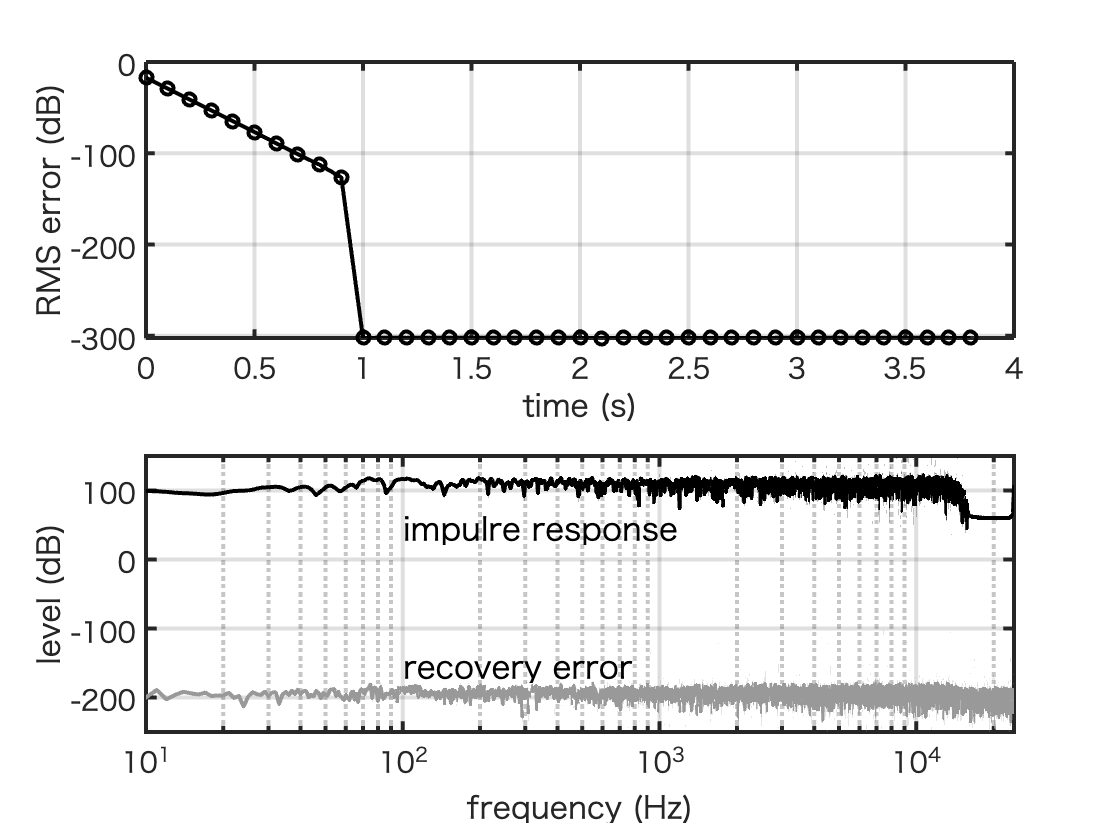

figure;
tiledlayout(2,1);
nexttile
plot(headLoc/fs,stdErr,"ko-","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
ylabel('RMS error (dB)')
nexttile
semilogx(fx,20*log10(abs(fft(a11))),"k","LineWidth",2);grid on;
hold all
semilogx(fx,20*log10(abs(fft(a11-hEstTrim))),"LineWidth",2,"Color",[0.6 0.6 0.6]);grid on;
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
text(100,50,"impulre response","FontSize",16)
text(100,-150,"recovery error","FontSize",16)
axis([10 fs/2 -250 150])
print -dpng mlsRSSErr.png

## MLS SNR test

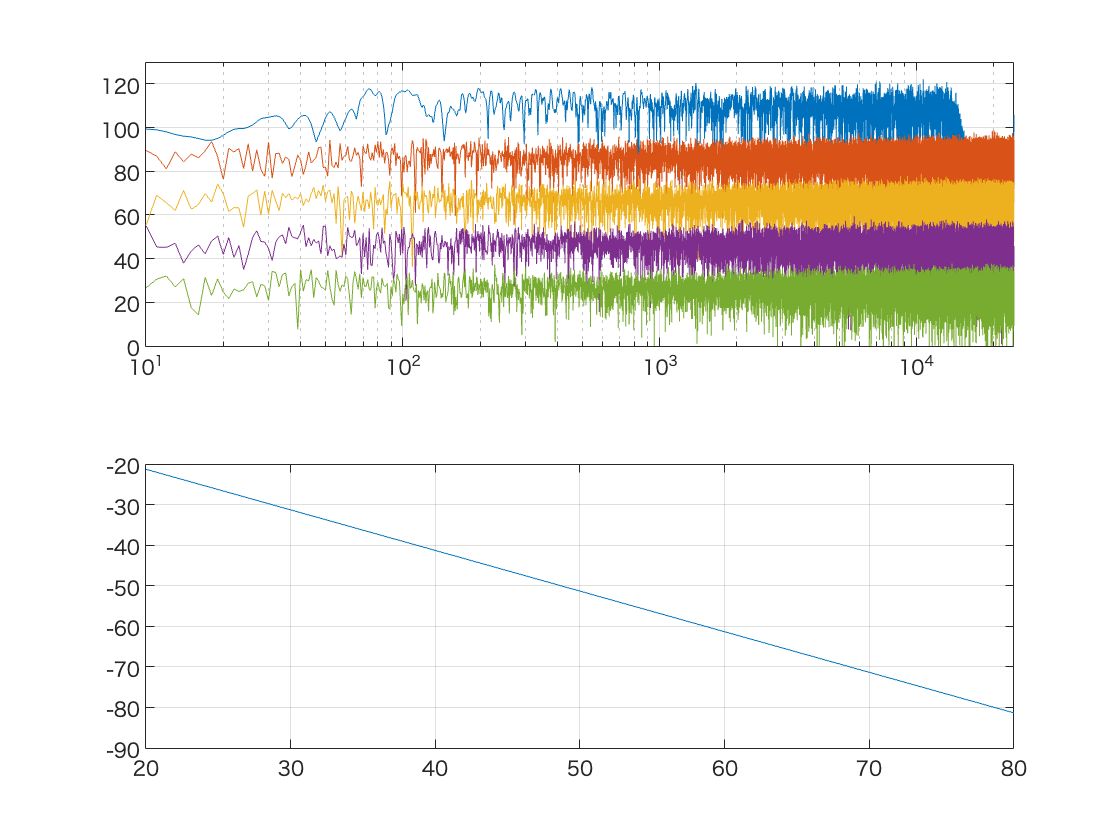

exita = mls(2^16-1);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(la11,length(snrList));
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx)+std(y(seleIdx))*randn(lPeriod,1)*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    hEst = hEstRaw(1:la11);
    errSpec(:,ii) = 20*log10(abs(fft(hEst-a11)));
    stdErr(ii) = 20*log10(std(hEst-a11)/std(a11));
end
figure;
tiledlayout(2,1)
t1 = nexttile;
semilogx(fx,20*log10(abs(fft(a11))));grid on
hold all
semilogx(fx,errSpec);grid on;
axis([10 fs/2 0 130])
t2 = nexttile;
plot(snrList,stdErr);grid on;

## MLS SNR test using LNN

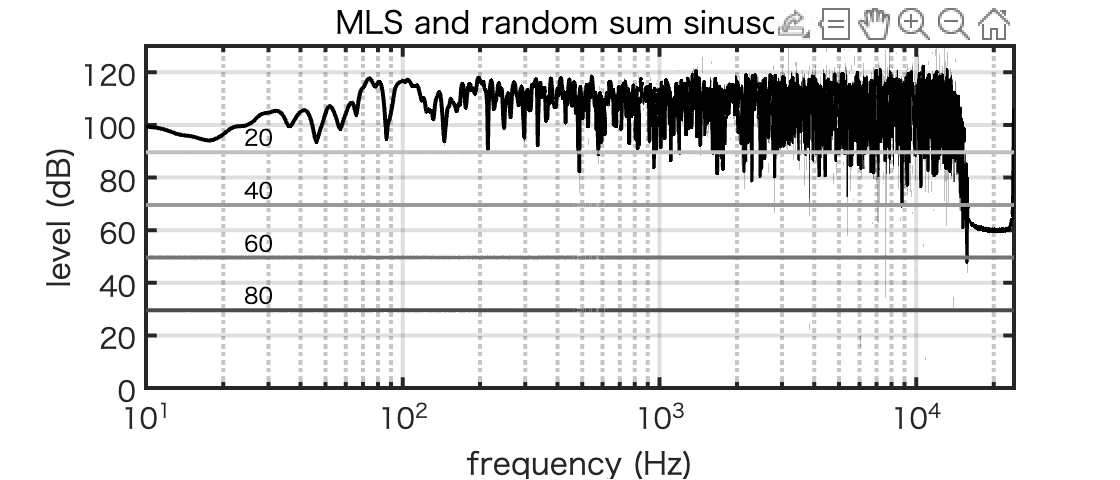

exita = mls(2^16-1);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 96;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("MLS and random sum sinusoids")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
%t2 = nexttile;
%plot(snrList,stdErr,"ko-");grid on;
print -dpng MLSmesRSsinusoidErr.png

## log-sewpt sine SNR test using LNN

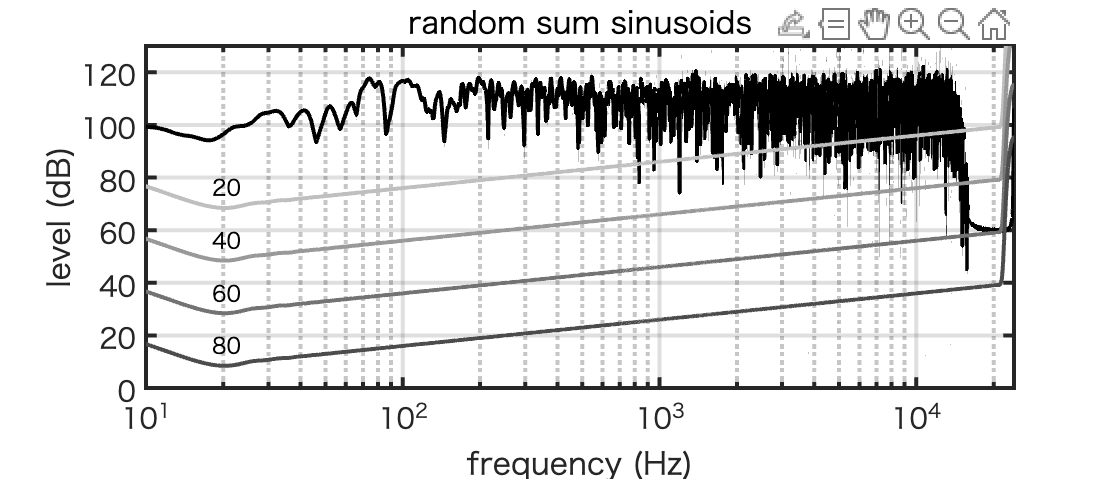

exita = sweeptone(0.99,0.01,fs);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
axis([10 fs/2 0 130])
hold all
%semilogx(fxx,errSpec);grid on;
colorLevel = 0.75;
hops = 77;
for ii = 1:length(snrList)
semilogx(fx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(18,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("random sum sinusoids")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng logSSmesRSsinusoidErr.png

nData = 2.0 .^(8:18);
nSDE = zeros(length(nData),1);
figure;
nIteration = 1000;
for kk = 1:nIteration
    for ii = 1:length(nData)
        pnn = generateWhiteLNN(nData(ii));
        pnn = pnn/std(pnn);
        yyy = erf(sort(pnn)/sqrt(2));
        ggg = (1:nData(ii))/nData(ii)*2-1;
        nSDE(ii) = std(yyy-ggg(:));
    end
    loglog(nData,nSDE,"Color",[0 0 0 0.01],"LineWidth",3);grid on;
    drawnow
    hold all
end
set(gca,"LineWidth",2,"fontsize",18)
title("sum of random phase sinusoids")
xlabel('number of sinusoids')
ylabel('deviation from error function')
print -dpng sumOfRandSinusoid.png

nData = 2.0 .^(8:18);
nSDE = zeros(length(nData),1);
figure;
nIteration = 1000;
for kk = 1:nIteration
    for ii = 1:length(nData)
        pnn = randn(nData(ii),1);
        yyy = erf(sort(pnn)/sqrt(2));
        ggg = (1:nData(ii))/nData(ii)*2-1;
        nSDE(ii) = std(yyy-ggg(:));
    end
    loglog(nData,nSDE,"Color",[0 0 0 0.01],"LineWidth",3);grid on;
    drawnow
    hold all
end
set(gca,"LineWidth",2,"fontsize",18)
title("Finite length Gaussian noise")
xlabel('length of sequence')
ylabel('deviation from error function')
print -dpng finiteLengthNormalDistribution.png

## Swarmchart test sum of sinusoids

nPower = (8:2:18);
nData = 2.0 .^nPower;
nIteration = 1000;
nSDE = zeros(length(nData),nIteration);
for kk = 1:nIteration
    for ii = 1:length(nData)
        pnn = generateWhiteLNN(nData(ii));
        pnn = pnn/std(pnn);
        yyy = erf(sort(pnn)/sqrt(2));
        ggg = (1:nData(ii))/nData(ii)*2-1;
        nSDE(ii,kk) = std(yyy-ggg(:));
    end
end


figure;
for ii = 1:length(nData)
    swarmchart(nPower(ii)*ones(1,nIteration),nSDE(ii,:),"ko","filled","MarkerFaceAlpha",0.1, ...
        "MarkerFaceColor","flat");
    grid on
    hold on
end
yscale(gca,"log")
set(gca,"Box","on","FontSize",18,"LineWidth",2)
axis([7 19 0.0003 0.1])
title("sum of random phase sinusoids")
xlabel('2^N, number of sinusoids')
ylabel('deviation from error function')
%set(gcf,"position",[680 458 560 240])
print -dpng sumOfRandSinusoid.png

## Swarmchart test Gaussian noise

nPower = (8:2:18);
nData = 2.0 .^nPower;
nIteration = 1000;
nSDE = zeros(length(nData),nIteration);
for kk = 1:nIteration
    for ii = 1:length(nData)
        %pnn = generateWhiteLNN(nData(ii));
        %pnn = pnn/std(pnn);
        pnn = randn(nData(ii),1);
        yyy = erf(sort(pnn)/sqrt(2));
        ggg = (1:nData(ii))/nData(ii)*2-1;
        nSDE(ii,kk) = std(yyy-ggg(:));
    end
end

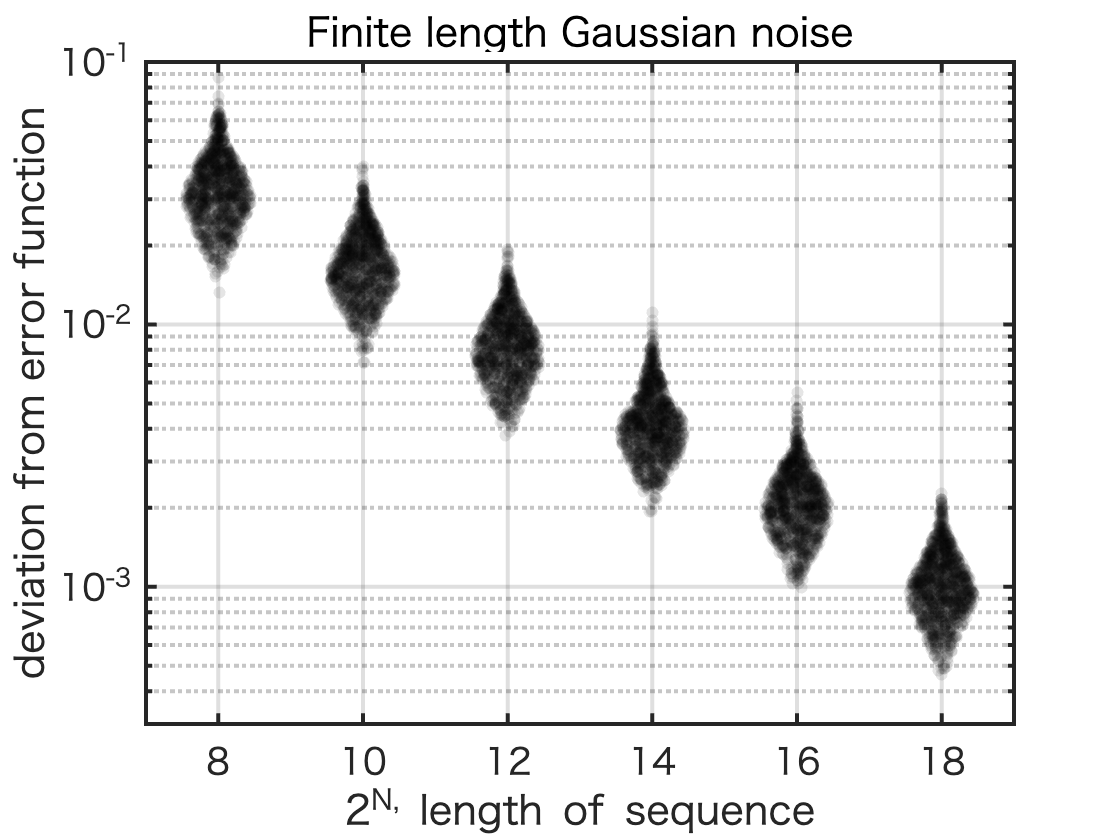


figure;
for ii = 1:length(nData)
    swarmchart(nPower(ii)*ones(1,nIteration),nSDE(ii,:),"ko","filled","MarkerFaceAlpha",0.1, ...
        "MarkerFaceColor","flat");
    grid on
    hold on
end
yscale(gca,"log")
set(gca,"Box","on","FontSize",18,"LineWidth",2)
axis([7 19 0.0003 0.1])
title("Finite length Gaussian noise")
xlabel('2^N, length of sequence')
ylabel('deviation from error function')
%set(gcf,"position",[680 458 560 240])
print -dpng finiteLengthNormalDistribution.png

## log-sewpt sine SNR test using LNN temporal response

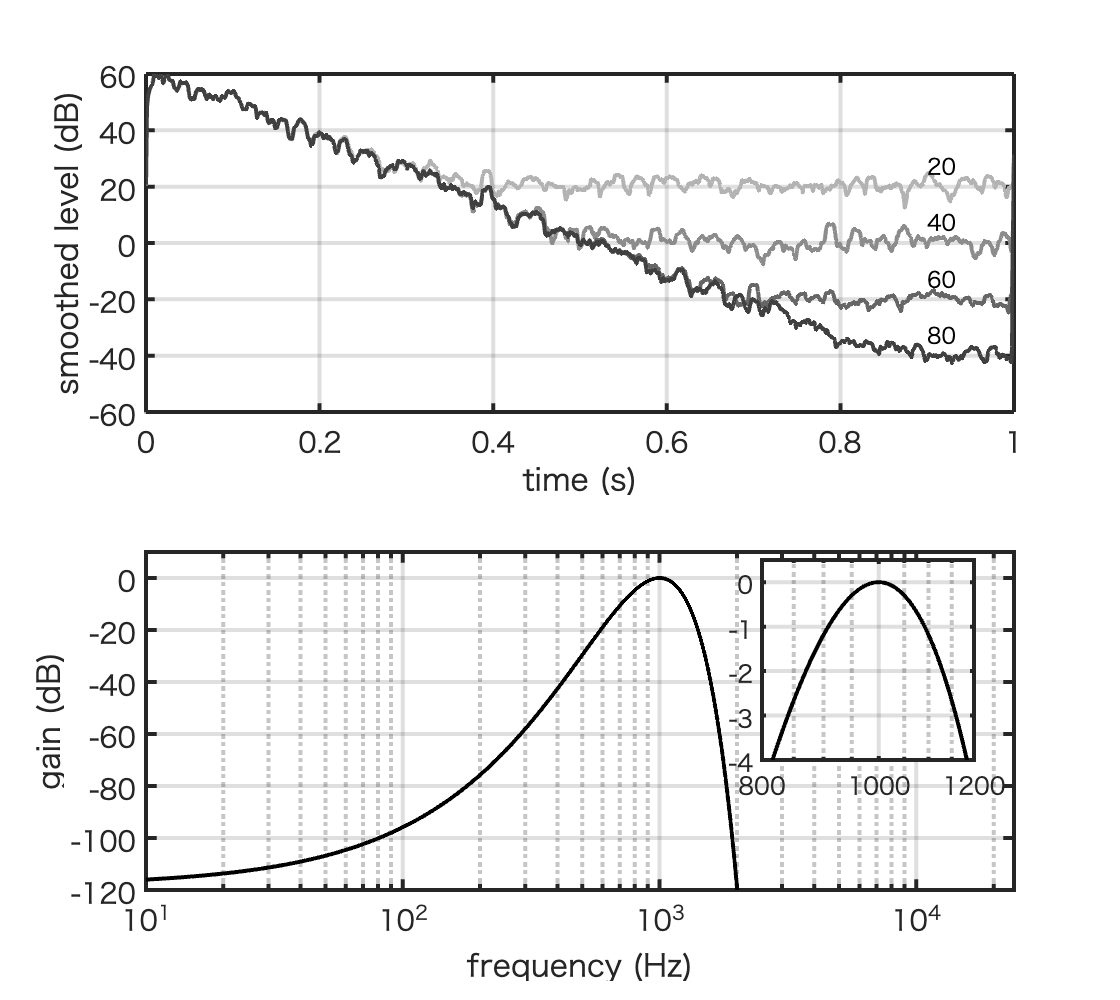

exita = sweeptone(0.99,0.01,fs);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
fxx = (0:lPeriod-1)'/lPeriod*fs;
fxBi = fxx;
fxBi(fxx>fs/2) = fxBi(fxx>fs/2)-fs;
%sel1k = abs(fxBi)>1000/sqrt(2) & abs(fxBi)<1000*sqrt(2);
%bpfRespF = 20*log10(exp(-(logFreqAx-1000).^2/9.4^5));
sel1k = exp(-(abs(fxBi)-1000).^2/9.4^5);
respList = zeros(fs,length(snrList));
colorLevel = 0.7;
hops = 28;
figure;
set(gcf,"position",[680 458 560 500])
tiledlayout(2,1);
t2 = nexttile;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
    hEst1k = real(ifft(sel1k.*fft(ySeg)./fft(xTstSeg)));
    respList(:,ii) = hEst1k;
    plot((1:fs)/fs,10*log10(fftfilt(ones(48*10,1)/480,abs(hEst1k).^2)),"LineWidth",2,"Color",colorLevel*[1 1 1]);grid on
    hold on
    text(0.9,hops,num2str(snrList(ii)))
    drawnow
    colorLevel = colorLevel-0.15;
    hops = hops - 20;
end
set(gca,"LineWidth",2,"fontsize",14)
xlabel("time (s)")
ylabel("smoothed level (dB)")
t1 = nexttile;
semilogx(fxx,20*log10(sel1k),"k","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",14)
axis([10 fs/2 -120 10]);
xlabel("frequency (Hz)")
ylabel("gain (dB)")
axes('Position',[0.68 0.24 0.19 0.2]);
semilogx(fxx,20*log10(sel1k),"k","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",12)
axis([800 1200 -4 0.5]);
print -dpng powerDecay.png

## SG signal recovery test

[xtmp,fstmp] = audioread("bak48kHK0dB.wav");
exita = xtmp;
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = 1:round(0.1*fs):round(6.9*fs);
stdErr = zeros(length(headLoc),1);
for ii = 1:length(headLoc)
    seleIdx = headLoc(ii)+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx);
    hEst = real(ifft(fft(ySeg)./fft(xTstSeg)));
    hEstTrim = hEst(1:la11);
    stdErr(ii) = 20*log10(std(hEstTrim-a11)/std(a11));
end

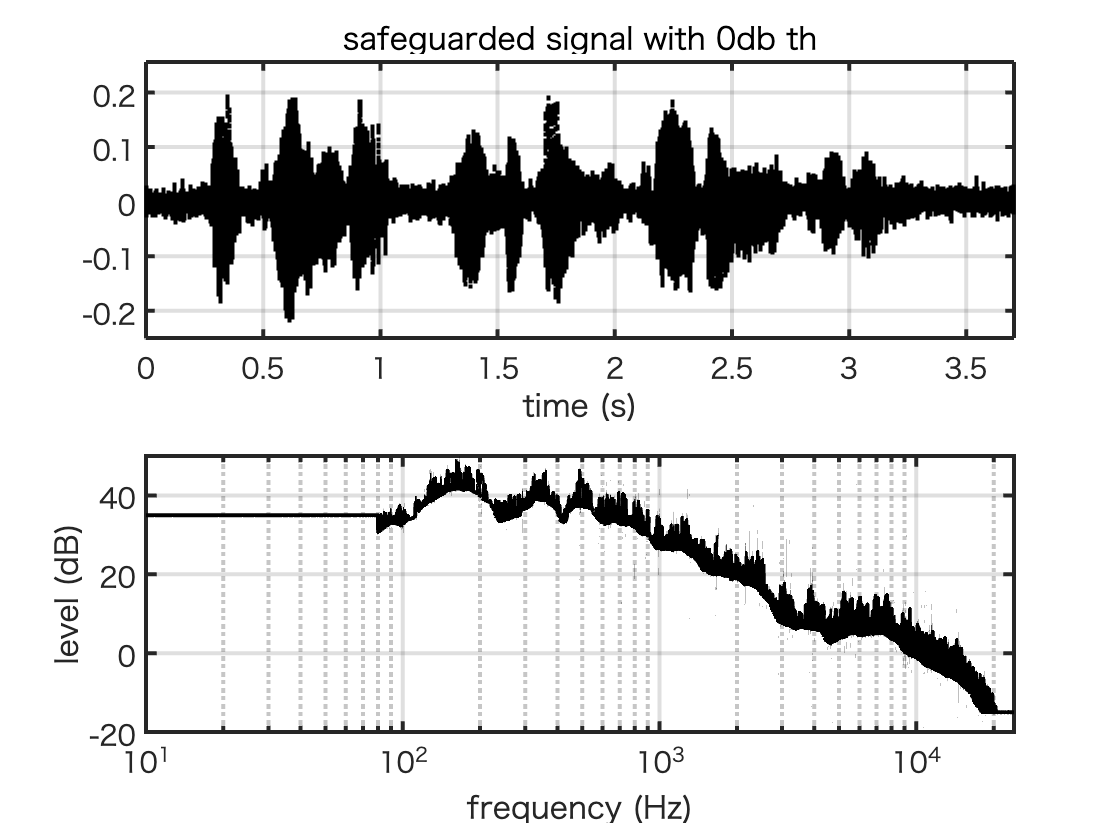


figure;
tiledlayout(2,1)
nexttile
plot((1:lPeriod)/fs,exita,"k.");grid on
axis([0 lPeriod/fs -0.6 0.6])
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
axis([0 lPeriod/fs -0.25 0.256])
title("safeguarded signal with 0db th")
nexttile;
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(exita))),"k","LineWidth",2);grid on
%set(gca,"xlim",[10 fs/2])
set(gca,"LineWidth",2,"fontsize",14)
axis([10 fs/2 -20 50])
%t2 = nexttile;
%plot(headLoc/fs,stdErr);grid on;
xlabel('frequency (Hz)')
ylabel('level (dB)')

%print -dpng MLStestSignal.png

## check error

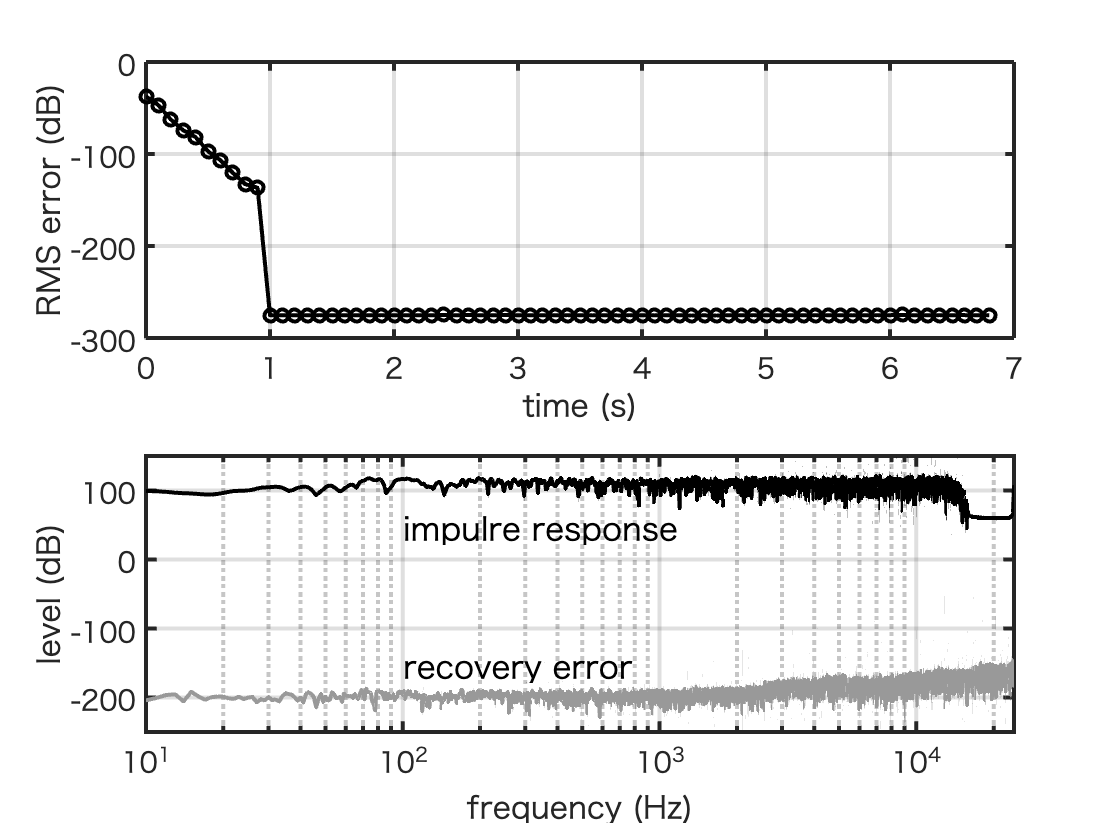

figure;
tiledlayout(2,1);
fxo = (0:la11-1)'/la11*fs;
nexttile
plot(headLoc/fs,stdErr,"ko-","LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",14)
xlabel('time (s)')
ylabel('RMS error (dB)')
nexttile
semilogx(fxo,20*log10(abs(fft(a11))),"k","LineWidth",2);grid on;
hold all
semilogx(fxo,20*log10(abs(fft(a11-hEstTrim))),"LineWidth",2,"Color",[0.6 0.6 0.6]);grid on;
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
text(100,50,"impulre response","FontSize",16)
text(100,-150,"recovery error","FontSize",16)
axis([10 fs/2 -250 150])
print -dpng sgSigRSSErr.png

## SG signal SNR test using LNN

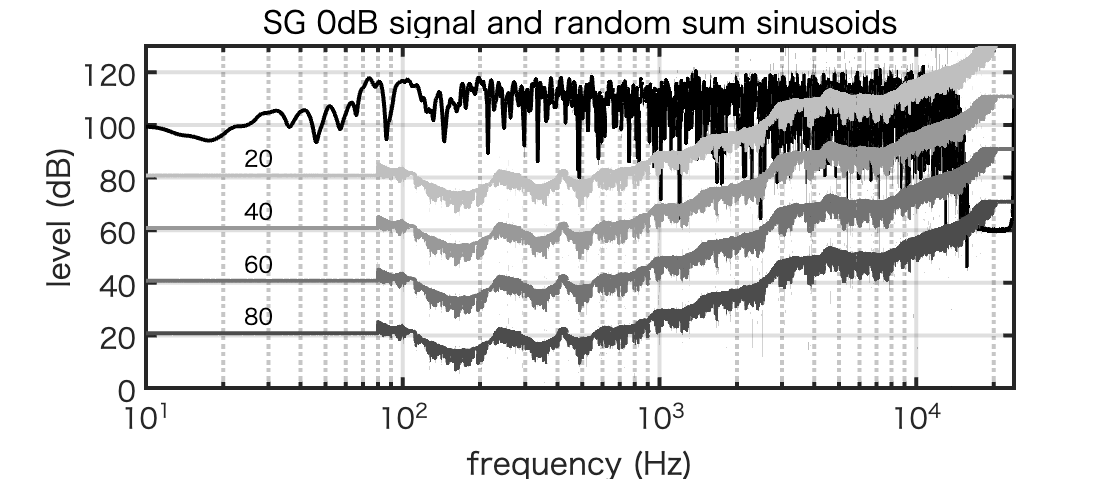

%exita = mls(2^16-1);
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 88;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("SG 0dB signal and random sum sinusoids")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng sg0dBSigmesRSsinusoidErr.png

## SG signal SNR test using LNN 10dB

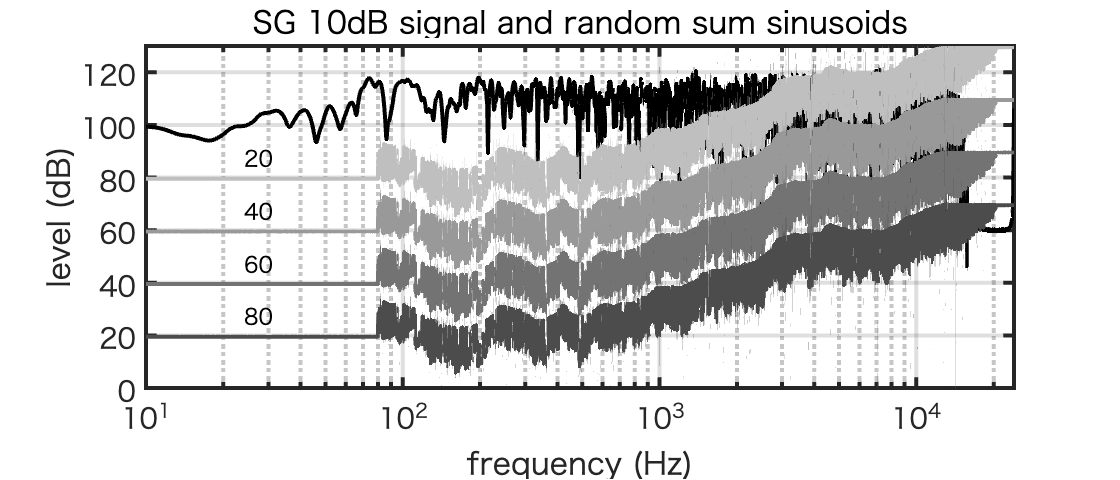

%exita = mls(2^16-1);
[xtmp,fstmp] = audioread("bak48kHK10dB.wav");
exita = xtmp;
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 88;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("SG 10dB signal and random sum sinusoids")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng sg10dBSigmesRSsinusoidErr.png

## SG signal SNR test using LNN 10dB pink

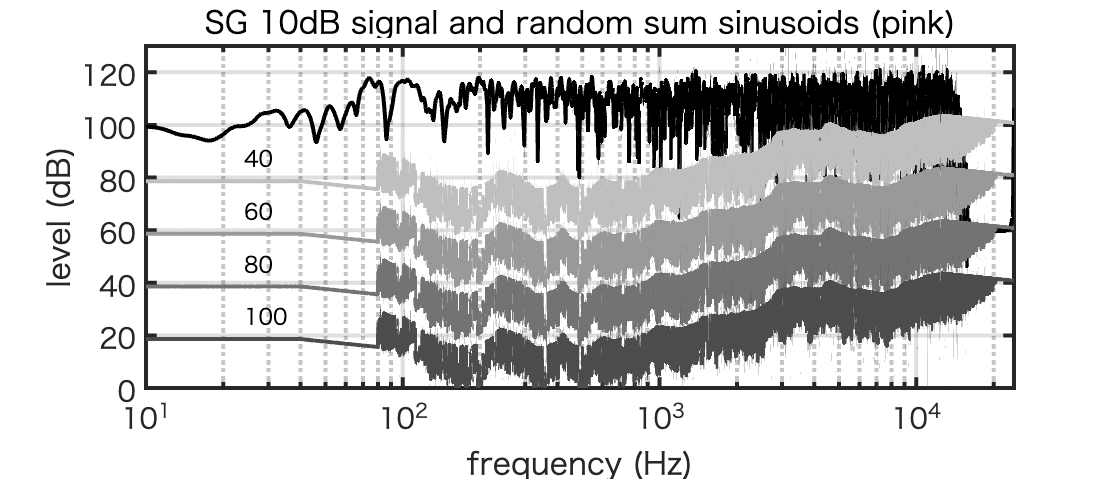

%exita = mls(2^16-1);
[xtmp,fstmp] = audioread("bak48kHK10dB.wav");
exita = xtmp;
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 40:20:100;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generatePinkLNN(lPeriod,fs);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 88;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("SG 10dB signal and random sum sinusoids (pink)")
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng sg10dBSigmesRSsinusoidPinkErr.png

tput = periodicCAPRICEP4(fs,1,20,"Erf");

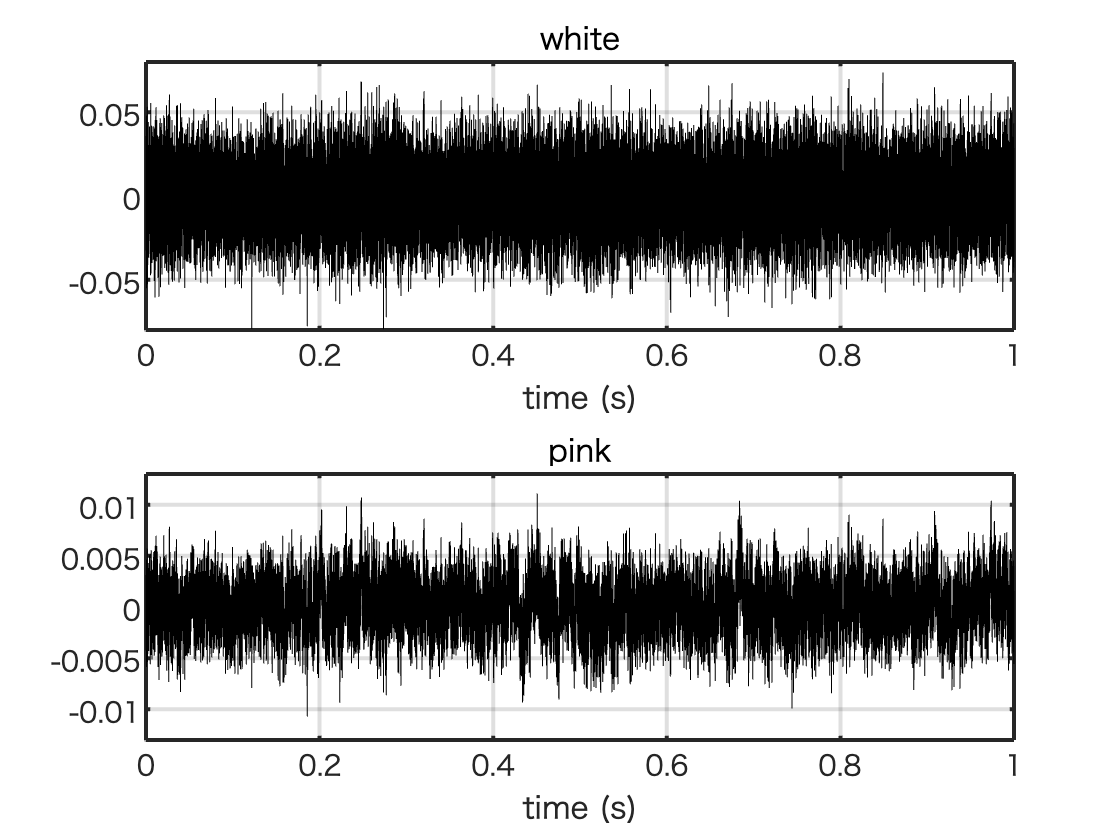

figure;
tt = (1:fs)'/fs;
tiledlayout(2,1)
nexttile
plot(tt,tput.unitWhite,"k");grid on
set(gca,"LineWidth",2,"fontsize",14)
title("white");
xlabel("time (s)")
axis([0 1 -0.08 0.08])
nexttile
plot(tt,tput.unitPink,"k");grid on;
set(gca,"LineWidth",2,"fontsize",14)
title("pink");
xlabel("time (s)")
axis([0 1 -0.013 0.013])
print -dpng strCAPsigWave.png

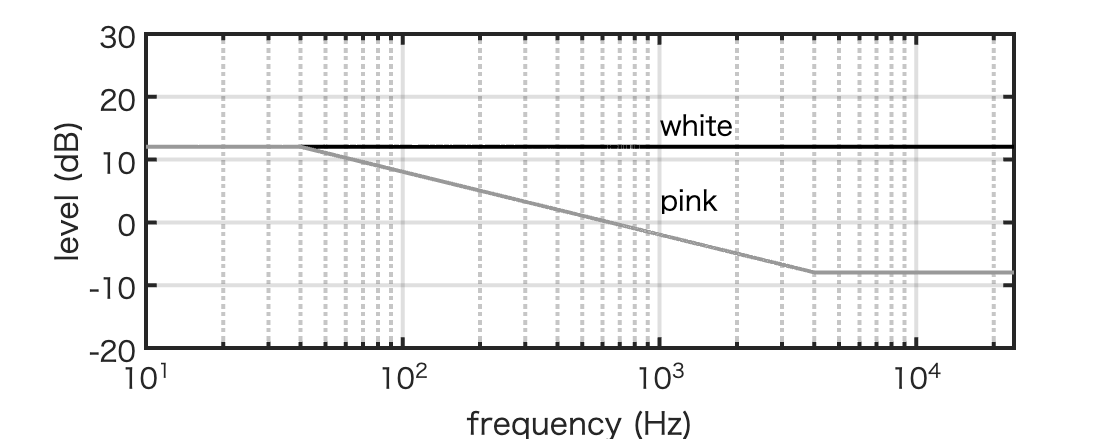


fx = (0:fs-1)';
figure;
set(gcf,"position",[680 458 560 220])
semilogx(fx,20*log10(abs(fft(tput.unitWhite))),"k","LineWidth",2);grid on;
hold all
semilogx(fx,20*log10(abs(fft(tput.unitPink))),"LineWidth",2,"Color",0.6*[1 1 1]);grid on;
axis([10 fs/2 -20 30])
text(1000,16, "white","fontsize",14)
text(1000,4, "pink","fontsize",14)
set(gca,"LineWidth",2,"fontsize",14)
xlabel('frequency (Hz)')
ylabel('level (dB)')
print -dpng strCAPspectrum.png

## structured CAPRICEP test signal with Erf (white)

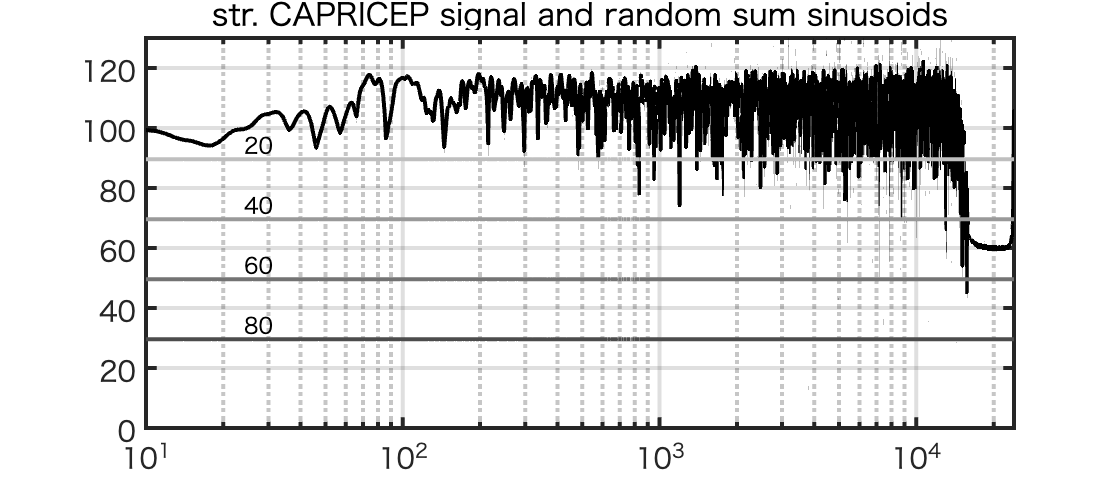

exita = tput.unitWhite;
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    xTstSeg = xTst(seleIdx);
    pnn = generateWhiteLNN(lPeriod);
    pnn = pnn/std(pnn);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 95;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("str. CAPRICEP signal and random sum sinusoids")
set(gca,"LineWidth",2,"fontsize",14)
print -dpng strCAPSigmesRSsinusoidWhiteErr.png

## structured CAPRICEP test signal with Erf (pink pink)

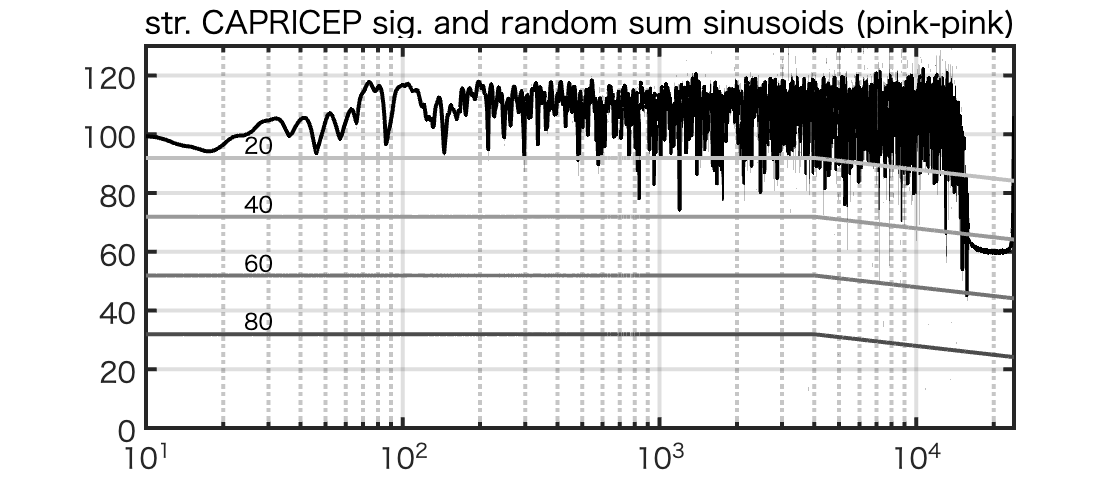

exita = tput.unitPink;
lPeriod = length(exita);
xTst = [exita;exita;exita;exita;exita];
y = fftfilt(a11,xTst);
headLoc = round(3.9*fs);
snrList = 20:20:80;
stdErr = zeros(length(snrList),1);
errSpec = zeros(lPeriod,length(snrList));
a11Ext = zeros(lPeriod,1);
a11Ext(1:fs) = a11;
eltList = zeros(length(snrList),1);
for ii = 1:length(snrList)
    seleIdx = headLoc+(1:lPeriod);
    pnn = generatePinkLNN(lPeriod,fs);
    pnn = pnn/std(pnn);
    tic;
    xTstSeg = xTst(seleIdx);
    ySeg = y(seleIdx)+std(y(seleIdx))*pnn*10^(-snrList(ii)/20);
    hEstRaw = real(ifft(fft(ySeg)./fft(xTstSeg)));
    eltList(ii) = toc;
    errSpec(:,ii) = 20*log10(abs(fft(hEstRaw-a11Ext)));
    stdErr(ii) = 20*log10(std(hEstRaw-a11Ext)/std(a11Ext));
end
figure;
%tiledlayout(2,1)
%t1 = nexttile;
set(gcf,"position",[680 458 560 240])
fxx = (0:lPeriod-1)'/lPeriod*fs;
semilogx(fxx,20*log10(abs(fft(a11Ext))),"k","LineWidth",2);grid on
hold all
%semilogx(fxx,errSpec);grid on;
axis([10 fs/2 0 130])
colorLevel = 0.75;
hops = 97;
for ii = 1:length(snrList)
semilogx(fxx,errSpec(:,ii),"LineWidth",2,"Color",colorLevel*[1 1 1]);
colorLevel = colorLevel-0.15;
text(24,hops,num2str(snrList(ii)))
hops = hops-20;
end
title("str. CAPRICEP sig. and random sum sinusoids (pink-pink)")
set(gca,"LineWidth",2,"fontsize",14)
print -dpng strCAPSigmesRSsinusoidPkPkErr.png